# FNN CNN LSTM 

%clear

## 저장된 데이타를 모두 읽어들인다.

%{
load data_05 
load data_06 
load data_07 
load data_0506 
load data_0606 
load data_05plus06      
load data_05plus07      
load data_06plus07      
load data_05plus06plus07

load cap_05             
load cap_06             
load cap_07             
load cap_0506           
load cap_0605           
load cap_05plus06       
load cap_05plus07       
load cap_06plus07       
load cap_05plus06plus07 
%}

load charVIT_05
load charVIT_06
load charVIT_07
load charVIT_0506              
load charVIT_0605              
load charVIT_05plus06          
load charVIT_05plus07          
load charVIT_06plus07          
load charVIT_05plus06plus07    

load InitC_05 				
load InitC_06 				
load InitC_07 				
load InitC_0506 			
load InitC_0605 			
load InitC_05plus06 		
load InitC_05plus07 		
load InitC_06plus07 		
load InitC_05plus06plus07 	

load charVIT_input_size                  
load charVIT_05plus06_input_size         
load charVIT_05plus07_input_size         
load charVIT_06plus07_input_size         
load charVIT_05plus06plus07_input_size  

load xB_gen_05 yB_gen_05 ym_gen_05 yr_gen_05
load xB_gen_06 yB_gen_06 ym_gen_06 yr_gen_06
load xB_gen_07 yB_gen_07 ym_gen_07 yr_gen_07
load xB_05 yB_05 ym_05 yr_05
load xB_06 yB_06 ym_06 yr_06
load xB_07 yB_07 ym_07 yr_07
load xB_0506 yB_0506 ym_0506 yr_0506
load xB_0605 yB_0605 ym_0605 yr_0605
load xB_05plus06 yB_05plus06 ym_05plus06 yr_05plus06
load xB_05plus07 yB_05plus07 ym_05plus07 yr_05plus07
load xB_06plus07 yB_06plus07 ym_06plus07 yr_06plus07
load xB_05plus06plus07 yB_05plus06plus07 ym_05plus06plus07 yr_05plus06plus07


BatteryNum = 56;
switch BatteryNum
    case 5
        Train_Input = xB_05;
        Train_Output = yB_05';
        yr = yr_05;
        ym = ym_05;
    case 6
        Train_Input = xB_06;
        Train_Output = yB_06';
        yr = yr_06;
        ym = ym_06;
    case 7
        Train_Input = xB_07;
        Train_Output = yB_07';
        yr = yr_07;
        ym = ym_07;
    case 56
        Train_Input = xB_0506;
        Train_Output = yB_0506';
        yr = yr_0506;
        ym = ym_0506;
    case 65
        Train_Input = xB_0605;
        Train_Output = yB_0605';
        yr = yr_0605;
        ym = ym_0605;
    case 562
        Train_Input = xB_05plus06;
        Train_Output = yB_05plus06';
        yr = yr_05plus06;
        ym = ym_05plus06;  
    case 572
        Train_Input = xB_05plus07;
        Train_Output = yB_05plus07';
        yr = yr_05plus07;
        ym = ym_05plus07; 
    case 672
        Train_Input = xB_06plus07;
        Train_Output = yB_06plus07';
        yr = yr_06plus07;
        ym = ym_06plus07; 
    case 5673
        Train_Input = xB_05plus06plus07;
        Train_Output = yB_05plus06plus07';
        yr = yr_05plus06plus07;
        ym = ym_05plus06plus07;         
end

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.54 |         0.48 |       0.1436 |       0.1137 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.24 |         0.18 |       0.0292 |       0.0168 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.11 |         0.06 |       0.0058 |       0.0020 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.06 |         0.05 |       0.0017 |   

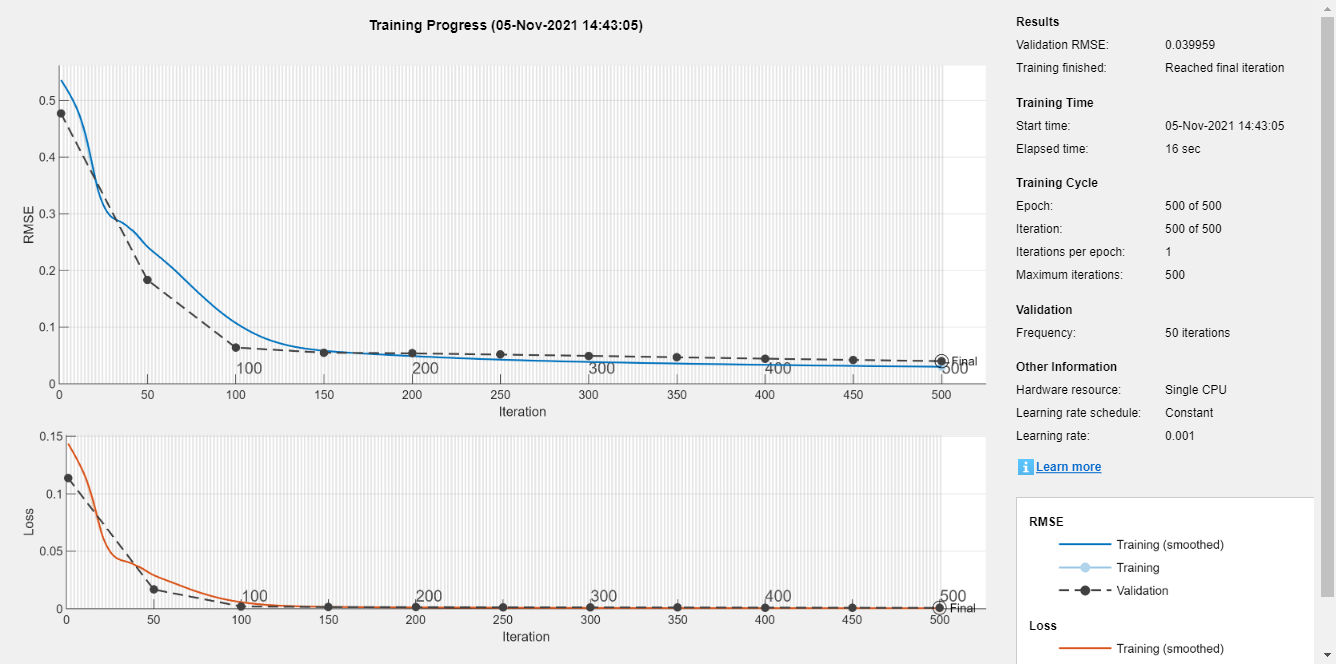

layerCNN1 = [
    imageInputLayer([1, charVIT_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.53 |         0.44 |       0.1414 |       0.0948 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.10 |         0.10 |       0.0051 |       0.0047 |          0.0010 |
|     100 |         100 |       00:00:06 |         0.06 |         0.05 |       0.0017 |       0.0013 |          0.0010 |
|     150 |         150 |       00:00:07 |         0.05 |         0.05 |       0.0010 |   

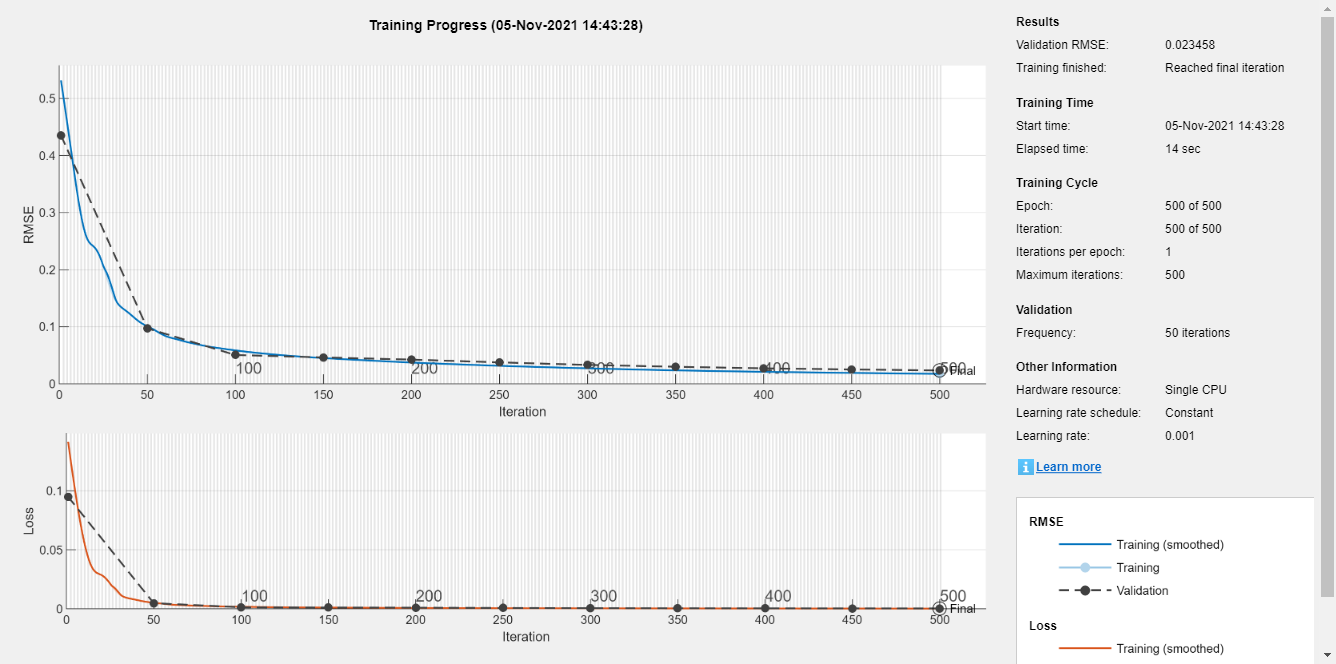

layerCNN2 = [
    imageInputLayer([1, charVIT_input_size]);
    convolution2dLayer([1, 2], charVIT_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.48 |         0.36 |       0.1150 |       0.0654 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.10 |         0.09 |       0.0045 |       0.0043 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.07 |         0.07 |       0.0026 |       0.0027 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.06 |         0.06 |       0.0018 |       0.0017 |          0.0010 |
|     20

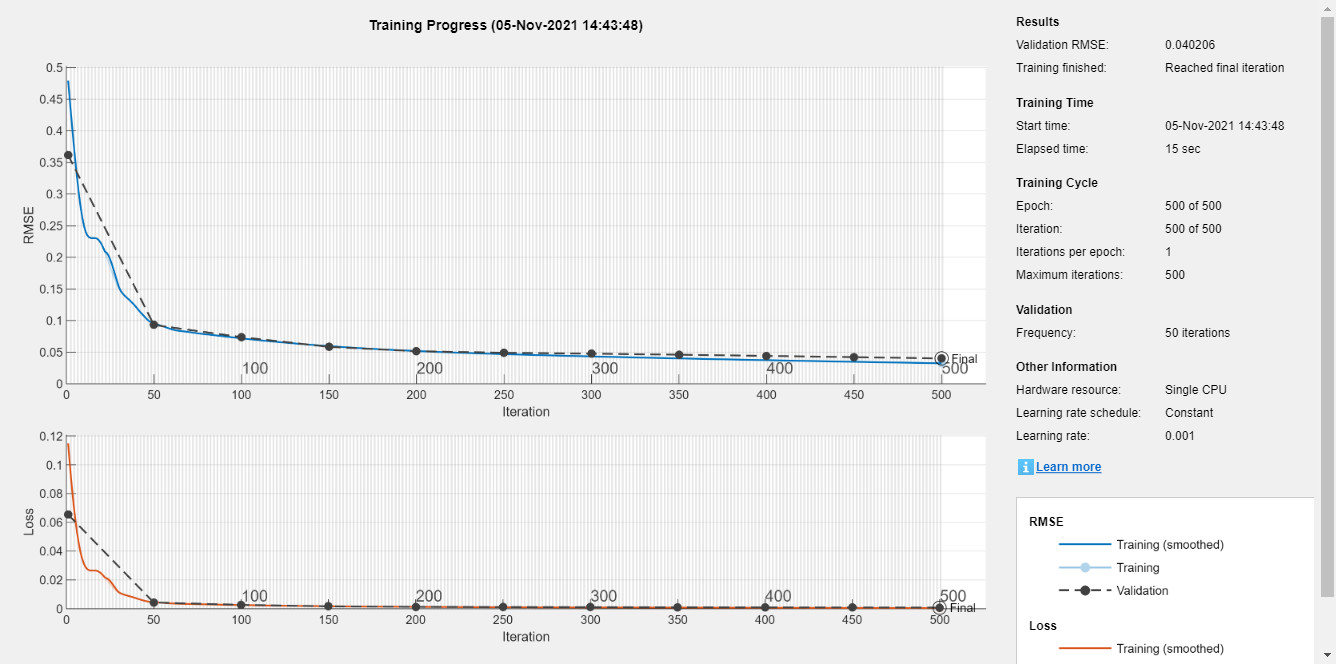

inputSize = charVIT_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.56 |         0.46 |       0.1582 |       0.1039 |          0.0010 |
|      50 |          50 |       00:00:09 |         0.10 |         0.09 |       0.0053 |       0.0043 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.07 |         0.07 |       0.0027 |       0.0025 |          0.0010 |
|     150 |         150 |       00:00:12 |         0.07 |         0.06 |       0.0021 |       0.0018 |          0.0010 |
|     20

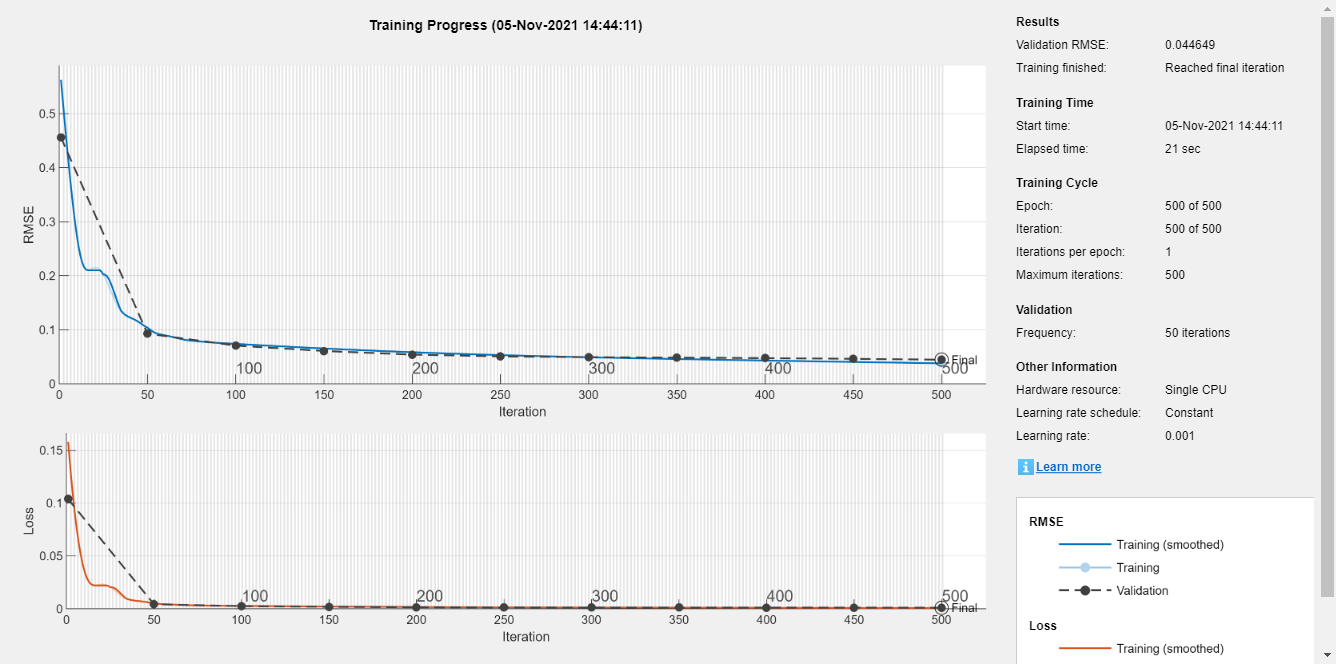

inputSize = charVIT_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_0506_v1 = netFNN40;
netCNN1_0506_v1 = netCNN1;
netCNN2_0506_v1 = netCNN2;
netLSTM_0506_v1 = netLSTM;
netGRU_0506_v1 = netGRU;

save  netFNN40_0506_v1 
save  netCNN1_0506_v1 
save  netCNN2_0506_v1 
save  netLSTM_0506_v1 
save  netGRU_0506_v1 


### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pFNN40 = pFNN40*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;
pLSTM = pLSTM*yr + ym;
pGRU = pGRU*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

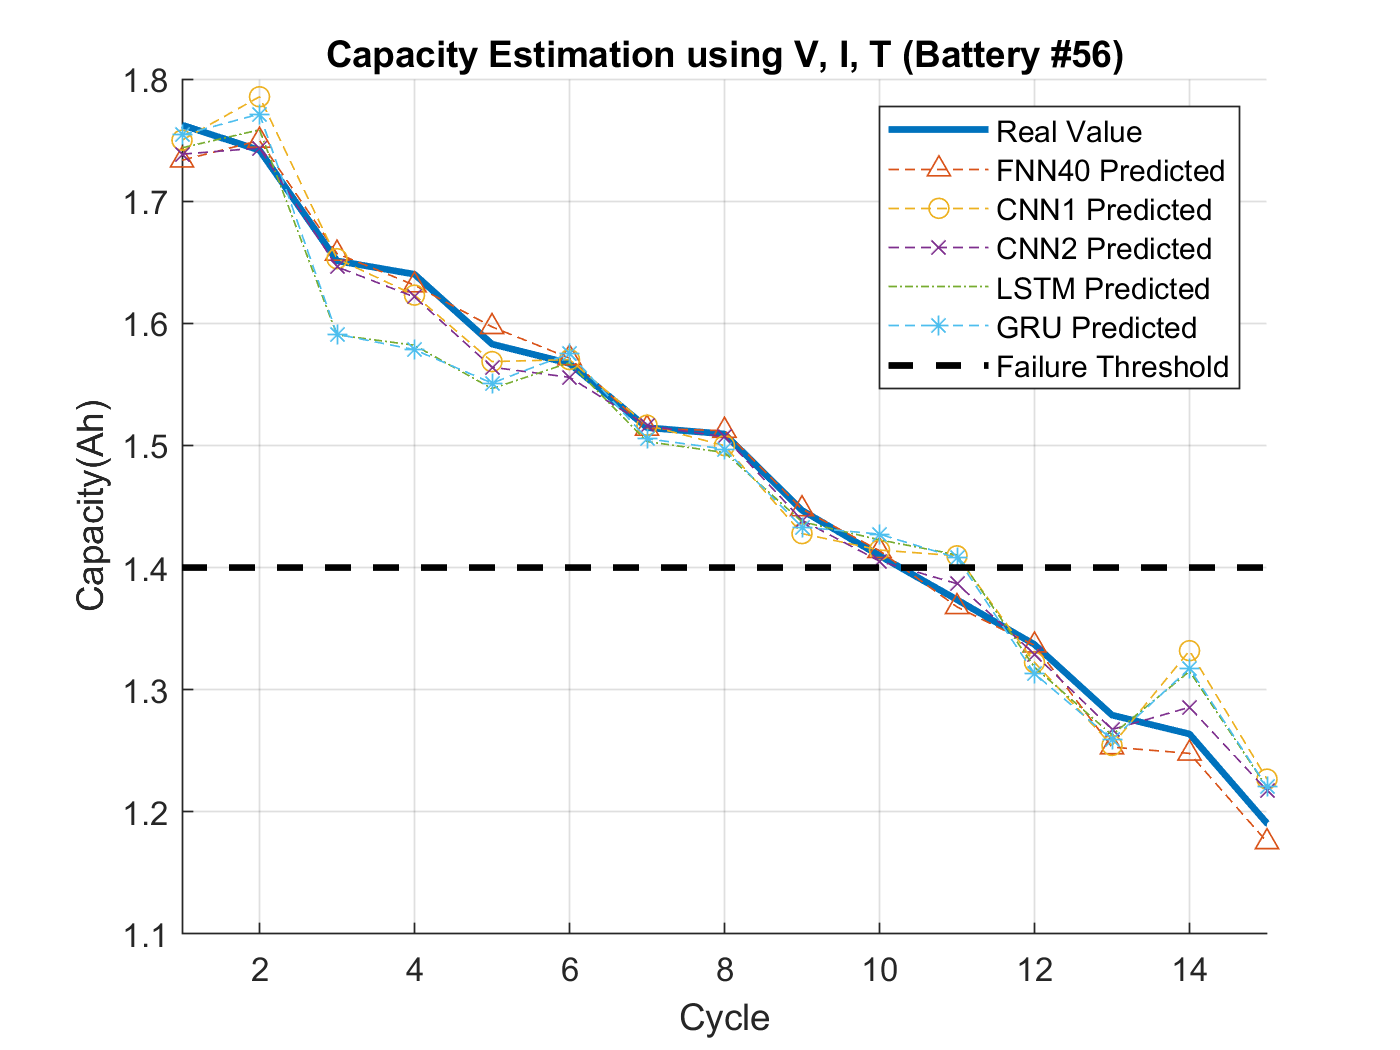

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:15, 1.4*ones(1, 15),'k--','LineWidth', 2), xlim([1 15])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))

rmse_pFNN40 = 0.0131

rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))

rmse_pCNN1 = single
0.0285

rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))

rmse_pCNN2 = single
0.0149

rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))

rmse_pLSTM = single
0.0315

rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

rmse_pGRU = single
0.0325

[1] B. Saha and K. Goebel, ``Battery data set,''NASA AMES Prognostics Data Repository, 2007.

[2] Choi, Yohwan, et al. "Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles." *IEEE Access* 7 (2019): 75143-75152.

***Copyright 2019 The MathWorks, Inc.***